# Portfolio Optimization of Power Generation Capacity

Code adapted from *Design Optimization of a Welded Beam, Mathworks.*

## Problem Description

In this problem we want to select the most sustainable power generation portfolios. We follow the approach of portfolio optimization, where we are concerned with both return and risk. In this case, we consider the Brundtland Commission's definition of sustainability, which is development that "meets the needs of the present generation without compromising the ability of future generations to meet their own needs." This is a powerful definition because it does relate both to return and risk. Generally we discount the risk to future generations, so it is a risk characterization. Meanwhile, the threats to immediate availability are taken carefully into consideration in making policies. Still, sustainable is a vague but powerful term, to paraphrase Solow (1991). Here we wish to quantify sustainability, so look at the triple bottom line to select sustainability indicators, modeling our approach on the work of Cartelle Barros et al. (2015), who conducted a comprehensive literature search and performed multi-criteria decision making to using a wide range of sustainability indicators from the economic, ecological and social categories. We revise their list and update and modify the list to account for different testbeds (PJM and CAISO).

As mentioned, there are two objectives in portfolio optimization: return and risk. 

Return in this case is current sustainability, or equitable availability of power generation. It will be modeled simply as shown here:


$$C=\sum_{t=1}^N x_t c_t$$


Subscript t refers to the technology, x is the weight of the technology and c is the cost of the technology in $/kw-yr.

Risk (R) includes correlation between different technologies, so is modeled as shown here:


$$R=\sqrt{\sum_i^N \sum_j^N x_i x_j \sigma_i \sigma_j \rho_{\textrm{ij}} }$$


 This time i and j both represent the technologies, again x is the weight of the technology, the sigma value is the risk for the technology, calculated based on the sustainability indicators related to future generations with rho representing the correlation between the two technology pairs. In this case, our initial assessment will make an assumption that there is no correlation between technologies, so the risk equations simplifies to the equation for cost.

The constraints on the problem are non-negativity constraints as well as the need for supply to be equal to demand. Since it is a continuous problem we can ignore the constraint of making supply equal to demand. The sum of the weights must be equal to 1.

The non-negativity constraint is dealt with below by creating bounds. The linear constraints are formulated by creating Aineq and bineq. In this case, the only linear constraint is that the sum of all x values must be equal to 1. 

Note that in this problem we have so far looked at 18 technologies, so that is set here.

clear
Number_Techs = 18;
Aineq = ones(1,Number_Techs);
VRE_Const = [1 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
Aineq = vertcat(Aineq, VRE_Const);
beq = 1;

- The bounds on all the variables are that they need to be greater than zero (non-negativity) and less than 1:

lb = zeros(1,Number_Techs);
ub = ones(1,Number_Techs);

The objective functions appear in the function my_obj_fun_Sustainability_PJM_no_corr`(x)`. 

## Multiobjective Problem Formulation and `paretosearch` Solution

The problem has been framed in many ways:

- Choose a starting point for costs and find optimal solutions using risk as a single objective (Arnesano et al.) 

- Find bounds close to existing bounds and analyze from there

- Construct a multiobjective problem, showing the variety of feasible solutions.

Here we attempt to solve as a multiobjective problem, which has the advantage of allowing us to understand many possible approaches and to obtain a sense of these solutions without designating a particular starting point. 

fun = @my_obj_fun_Sustainability_PJM_no_corr;

The `paretosearch` algorithmcan be plotted using `'psplotparetof'. Options are set here. The initial run is commented out since we have seen that they don't lead to attractive solutions.`

opts_ps = optimoptions('paretosearch','Display','off','PlotFcn','psplotparetof');
rng default % For reproducibility

%[x_ps1,fval_ps1,~,psoutput1] = paretosearch(fun,Number_Techs,[],[],Aineq,beq,lb,ub,[],opts_ps);
%disp("Total Function Count: " + psoutput1.funccount);

More points are necessary to have any approximation to the Pareto front in this problem. Increased points to 500.

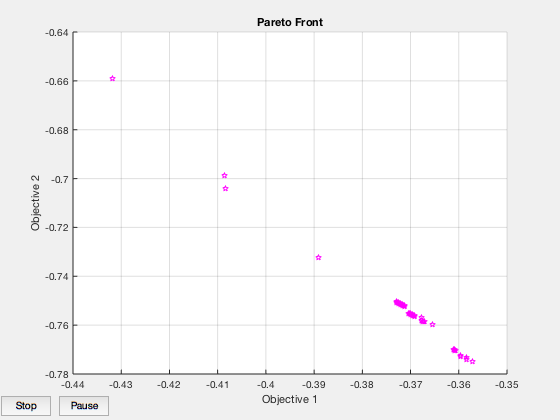

npts = 500; % The default is 60
opts_ps.ParetoSetSize = npts;
[x_ps2,fval_ps2,~,psoutput2] = paretosearch(fun,Number_Techs,[],[],Aineq,beq,lb,ub,[],opts_ps);

disp("Total Function Count: " + psoutput2.funccount);

Total Function Count: 45728


This requires many function runs.

## `gamultiobj` Solution

The `gamultiobj` solver is used with equivalent options but fewer points, since using more points made the ga very slow. 

npts=160;
opts_ga = optimoptions('gamultiobj','Display','off','PlotFcn','gaplotpareto','PopulationSize',2*npts);
%[x_ga1,fval_ga1,~,gaoutput1] = gamultiobj(fun,18,[],[],Aineq,beq,lb,ub,[],opts_ga);
%disp("Total Function Count: " + gaoutput1.funccount);

## Compare Solutions

Both are plotted together here, but this is commented out since it was no longer useful. 

% fps2 = sortrows(fval_ps2,1,'ascend');
% figure
% hold on
% plot(fps2(:,1),fps2(:,2),'r-')
% fga = sortrows(fval_ga1,1,'ascend');
% plot(fga(:,1),fga(:,2),'b--')
% xlim([-0.9,-0.4])
% ylim([-0.91,-0.7])
% legend('paretosearch','gamultiobj')
% xlabel 'Risk'
% ylabel 'Cost'
% hold off

## Start from Good Solutions

To improve the quality of the solutions, we decided to seed the solutions with each technology that has a score above 50% on either the cost or risk sustainability metrics.

x0 = xlsread('x_0_file_PJM.xlsx', 'a1:r24');
% x0f = (lb + ub)/2;
% opts_fmc = optimoptions('fmincon','Display','off','MaxFunctionEvaluations',1e4);
% x0(1,:) = fmincon(@(x)pickindex(x,1),x0f,[],[],Aineq,beq,lb,ub,[],opts_fmc);
% x0(2,:) = fmincon(@(x)pickindex(x,2),x0f,[],[],Aineq,beq,lb,ub,[],opts_fmc);
% my_obj_fun_Sustainability_PJM_no_corr(x0(1,:))
% my_obj_fun_Sustainability_PJM_no_corr(x0(2,:))

Now `paretosearch` is started from xo. 

% opts_ps.InitialPoints = x0;
% opts_ps.PlotFcn = [];
% [x_psx0,fval_ps1x0,~,psoutput1x0] = paretosearch(fun,Number_Techs,[],[],Aineq,beq,lb,ub,[],opts_ps);
% disp("Total Function Count: " + psoutput1x0.funccount);

We start `ga` from the same initial points, also removing its plot function.

opts_ga.InitialPopulationMatrix = x0;
opts_ga.PlotFcn = [];
[x_gax0,fval_gax0,~,gaoutput] = gamultiobj(fun,18,[],[],Aineq,beq,lb,ub,[],opts_ga);
disp("Total Function Count: " + gaoutput.funccount);

Total Function Count: 50880


The solutions are plotted.

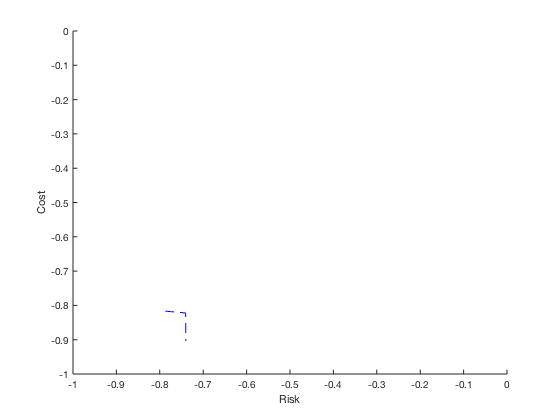

%fps = sortrows(fval_ps1x0,1,'ascend');
figure
hold on
%plot(fps(:,1),fps(:,2),'r-')
fga = sortrows(fval_gax0,1,'ascend');
plot(fga(:,1),fga(:,2),'b--')
xlim([-1,0])
ylim([-1,0])
% legend('paretosearch','gamultiobj')
xlabel 'Risk'
ylabel 'Cost'
hold off

function z = pickindex(x,k)
    z = my_obj_fun_Sustainability_PJM_no_corr(x); % evaluate both objectives
    z = z(k); % return objective k
end

## References

Mathworks, 2020. *Design Optimization of a Welded Beam. *[Online] 

Available at: https://www.mathworks.com/help/gads/multiobjective-optimization-welded-beam.html

[Accessed 19 June 2020].